start

clc;
clear;
x = linspace(0,15,100);

przedzialy poczatkowe

przedzialy = [6 8; 8.3 10; 12 15];

dokladnosc_zer = 0.001;
wielkosc_przedzialu = 0.01;
ilosc_iteracji = 100;

for i=1:3
    %wybor i-tego przedzialu
    if sprawdzenie_przedzialu(przedzialy(i,:)) == 0
        error('Error, zostaly wybrane zle przedzialy');
    end
end

wykres

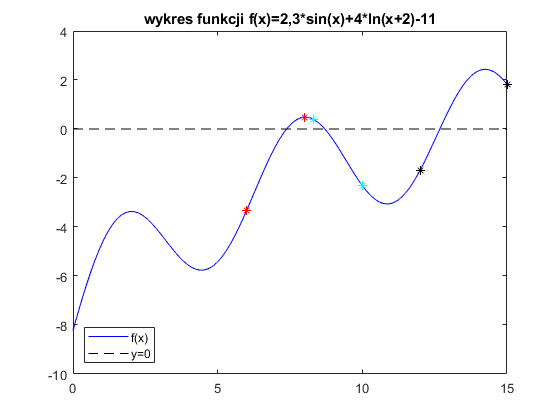

figure
y = wartosc_funkcji(x);
plot(x,y,'b-',[0 15], [0 0], 'k--', przedzialy(1,:), wartosc_funkcji(przedzialy(1,:)), 'r*', przedzialy(2,:), wartosc_funkcji(przedzialy(2,:)), 'c*', przedzialy(3,:), wartosc_funkcji(przedzialy(3,:)), 'k*');
legend({'f(x)', 'y=0'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

oszacowanie miejsc zerowych na podstawie rysunku (skrypt prof Tatjeskiego mowi, zeby estymowac na poodstawie rysunku)

% wartosc_funkcji(7.25)
% wartosc_funkcji(8)
% wartosc_funkcji(9)
% wartosc_funkcji(12.5)

porownanie

% przekroczenie przedzialu startowego
% x_styczne = met_stycznych([0 8], dokladnosc_zer, ilosc_iteracji)

x_bisekcja = bisekcja(przedzialy, dokladnosc_zer, wielkosc_przedzialu)

metoda bisekcji przedzial nr 1
x=7.000000 y=-0.700033
x=7.500000 y=0.162567
x=7.250000 y=-0.208420
x=7.375000 y=-0.006645
x=7.437500 y=0.082156
x=7.406250 y=0.038790
x=7.390625 y=0.016329
x=7.382813 y=0.004906
x=7.378906 y=-0.000853
metoda bisekcji przedzial nr 2
x=9.150000 y=-0.730176
x=8.725000 y=-0.028380
x=8.512500 y=0.229330
x=8.618750 y=0.110034
x=8.671875 y=0.043095
x=8.698438 y=0.007909
x=8.711719 y=-0.010100
x=8.705078 y=-0.001061
x=8.701758 y=0.003432
x=8.703418 y=0.001187
x=8.704248 y=0.000064
metoda bisekcji przedzial nr 3
x=13.500000 y=1.812064
x=12.750000 y=0.184950
x=12.375000 y=-0.775508
x=12.562500 y=-0.295103
x=12.656250 y=-0.054088
x=12.703125 y=0.065796
x=12.679688 y=0.005930
x=12.667969 y=-0.024062
x=12.673828 y=-0.009061
x=12.676758 y=-0.001564
x=12.678223 y=0.002183
x=12.677490 y=0.000310


x_bisekcja =     7.3789
    8.7042
   12.6775


x_sieczne = met_siecznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)

metoda siecznych przedzial nr 1
x=7.745004 y=0.393375
x=7.560390 y=0.232099
x=7.294705 y=-0.132650
x=7.391328 y=0.017351
x=7.380152 y=0.000986
metoda siecznych przedzial nr 2
x=8.552678 y=0.186585
x=8.769956 y=-0.092217
x=8.698089 y=0.008377
x=8.704074 y=0.000299
metoda siecznych przedzial nr 3
x=13.435563 y=1.703456
x=12.712354 y=0.089322
x=12.672334 y=-0.012885
x=12.677379 y=0.000026


x_sieczne =     7.3802
    8.7041
   12.6774


x_styczne = met_stycznych(przedzialy, dokladnosc_zer, ilosc_iteracji)

metoda stycznych przedzial nr 1
x=7.227625 y=-0.247805
x=7.366706 y=-0.019047
x=7.379371 y=-0.000167
metoda stycznych przedzial nr 2
x=8.968366 y=-0.406259
x=8.729374 y=-0.034459
x=8.704639 y=-0.000466
metoda stycznych przedzial nr 3
x=12.753573 y=0.193995
x=12.676923 y=-0.001141
x=12.677369 y=-0.000000


x_styczne =     7.3794
    8.7046
   12.6774


y_bisekcja = wartosc_funkcji(x_bisekcja)

y_bisekcja = 	1.0e+-3 *

   -0.8534
    0.0635
    0.3097


y_sieczne = wartosc_funkcji(x_sieczne)

y_sieczne = 	1.0e+-3 *

    0.9862
    0.2992
    0.0261


y_styczne = wartosc_funkcji(x_styczne)

y_styczne = 	1.0e+-3 *

   -0.1670
   -0.4659
   -0.0000


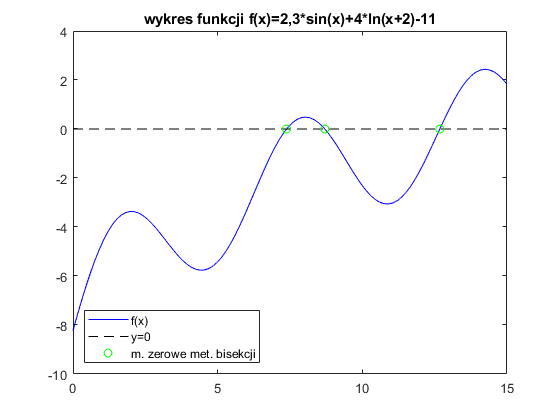


figure
plot(x,y,'b-',[0 15], [0 0], 'k--', x_bisekcja, wartosc_funkcji(x_bisekcja), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. bisekcji'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

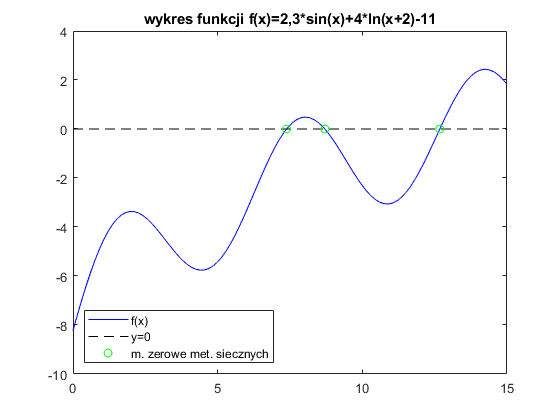


plot(x,y,'b-',[0 15], [0 0], 'k--', x_sieczne, wartosc_funkcji(x_sieczne), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. siecznych'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

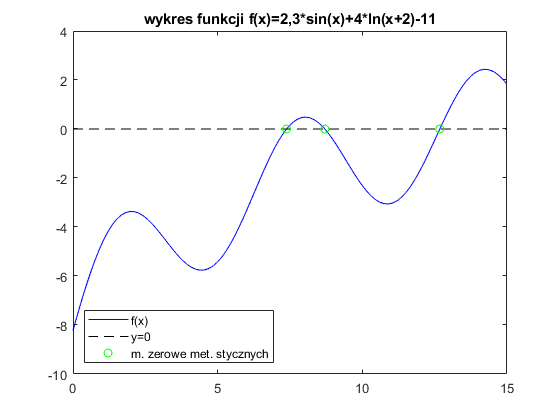


plot(x,y,'b-',[0 15], [0 0], 'k--', x_styczne, wartosc_funkcji(x_styczne), 'go');
legend({'f(x)', 'y=0', 'm. zerowe met. stycznych'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

**funkcje pomocnicze glowne**

**1. metoda bisekcji**

function x = bisekcja(przedzialy, dokladnosc_zer, wielkosc_przedzialu)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        fprintf('metoda bisekcji przedzial nr %d\n', i);
        iteracje = 0;
        c = 0;
        while (abs(wartosc_funkcji(c))>dokladnosc_zer | (przedzialy(i,2)-przedzialy(i,1))>wielkosc_przedzialu)
            iteracje = iteracje + 1;
            [c przedzialy(i,:)] = polowienie_przedzialu(przedzialy(i,:));
            fprintf('x=%f y=%f\n', c, wartosc_funkcji(c));
        end
        x(i) = c;
    end
end

polowienie przedzialow dla metody bisekcji

function [c nowy_przedzial] = polowienie_przedzialu(przedzial)
    c = (przedzial(1)+przedzial(2))/2;
    if(sprawdzenie_przedzialu([przedzial(1) c]) == 1)
        nowy_przedzial = [przedzial(1) c]; 
    else
        nowy_przedzial = [c przedzial(2)];
    end
end

**2. metoda siecznych**

function x = met_siecznych(przedzialy, dokladnosc_zer, wielkosc_przedzialu)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        fprintf('metoda siecznych przedzial nr %d\n', i);
        c = 0;
        while (abs(wartosc_funkcji(c))>dokladnosc_zer | (przedzialy(i,2)-przedzialy(i,1))>wielkosc_przedzialu)
            [c przedzialy(i,:)] = nowy_sieczny_przedzial(przedzialy(i,:), c);
            fprintf('x=%f y=%f\n', c, wartosc_funkcji(c));
        end
        x(i) = c;
    end
end

zmniejszenie przedzialow dla metody siecznych

function [d nowy_przedzial] = nowy_sieczny_przedzial(przedzial, c)
    d = wyznacz_zero_f_liniowej(przedzial);
    if(przedzial(2) == c)
        nowy_przedzial = [d przedzial(2)]; 
    else
        nowy_przedzial = [przedzial(1) d]; 
    end
end

wyznaczenie zera f. liniowej wyznaczonej na podstawie punktow z koncow przedzialu na podstawie wyliczonego analitycznie wzoru

function c = wyznacz_zero_f_liniowej(przedzial)
    x1 = przedzial(1);
    x2 = przedzial(2);
    y1 = wartosc_funkcji(x1);
    y2 = wartosc_funkcji(x2);
    c = (x2*y1-x1*y2)/(y1-y2);
end

**3. metoda stycznych**

function x = met_stycznych(przedzialy, dokladnosc_zer, ilosc_iteracji)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    for i = 1:ilosc_pierwiastkow
        fprintf('metoda stycznych przedzial nr %d\n', i);
        iteracje = 0;
        c = 0;
        pierwotny_przedzial = przedzialy(i,:);
        while (abs(wartosc_funkcji(c))>dokladnosc_zer & iteracje < ilosc_iteracji)
            iteracje = iteracje + 1;
            [c przedzialy(i,:)] = nowy_przedzial_styczny(przedzialy(i,:), pierwotny_przedzial);
            fprintf('x=%f y=%f\n', c, wartosc_funkcji(c));
        end
        x(i) = c;
    end
end

zmniejszenie przedzialow dla metody stycznych

function [d nowy_przedzial] = nowy_przedzial_styczny(przedzial, pierwotny_przedzial)
    d = nowy_punkt_styczny(przedzial(1));
    if(d >= pierwotny_przedzial(1) & d <= pierwotny_przedzial(2))
        nowy_przedzial = [d przedzial(2)];
    else
        disp(przedzial);
        disp(d);
        error('Error. Punkt poza przedzialem. Nalezy wybrac inny przedzial poczatkowy');
    end
end

wyznaczenie miejsca zerowego na podstawie pochodnej oraz poprzedniego punktu

function x0 = nowy_punkt_styczny(x)
    m = wartosc_pochodnej(x);
    y = wartosc_funkcji(x);
    x0 = (m*x-y)/m;
end

wyznaczenie pochodnej dla podanych x-ow

function y = wartosc_pochodnej(x)
    y = 23*cos(x)/10+4/(x+2);
end

**funkcje pomocnicze dodatkowe**

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = wartosc_funkcji(x)
    [temp rozmiar_x] = size(x);
    if rozmiar_x == 1
        x = x';
        rozmiar_x = temp;
    end
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        y(i,1) = 2.3*sin(x(1,i))+4*log(x(1,i)+2)-11;
    end
end

sprawdzenie czy w podanym przedziale jest miejsce zerowe

function result = sprawdzenie_przedzialu(przedzial)
    if wartosc_funkcji(przedzial(1))*wartosc_funkcji(przedzial(2)) < 0
        result = 1;
    else
        result = 0;
    end
end

wartosc najwiekszego bledu

function y = najwieksze_zero(x)
    y = max(abs(wartosc_funkcji(x)));
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end